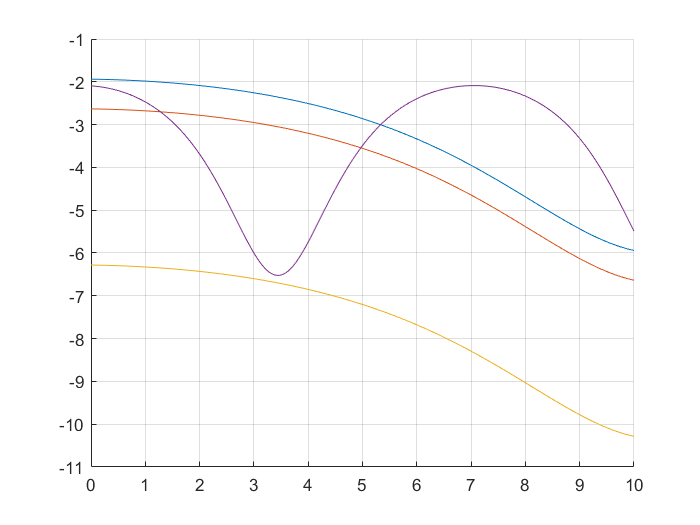

clear;

E_air = 1;
E_oil = 3;
theta = 0;
clf;
% planar -> ks = 0
% smooth -> ks = 0.2
% rough -> ks = 0.5
thickness = linspace(0, 10, 200);

raw12 = field_reflection_coefficient(sqrt(E_air), sqrt(E_oil));

close all;


% % %reflectivity at 4GHz
% 
% R4 = reflectivity(12, thickness, 0, E_oil, 1, 20, 35, 0);
% 
% %12 GHz
% 
% R12 = reflectivity(12, thickness, 0, E_oil, 1, 20, 35, 0);
% 
% hold on;
% plot(thickness, 10*log10(abs(R4)));
% plot(thickness, 10*log10(abs(R12)));
% grid on;
% hold off;
% figure;

% % Figure 2
 hold on;
R_f4_planar = reflectivity(4, thickness, 0, E_oil, 1, 20, 35, 0);
R_f4_smooth = reflectivity(4, thickness, 0.2, E_oil, 1, 20, 35, 0);
R_f4_rough = reflectivity(4, thickness, 0.5, E_oil, 1, 20, 35, 0);
% R_water_f4_planar = ones(1, 200) * ((sqrt(E_air) - sqrt(E_water_4GHz))/(sqrt(E_air) + sqrt(E_water_4GHz)))^2;
R12 =reflectivity(12, thickness, 0, E_oil, 1, 20, 35, 0);
grid on;


plot(thickness, 10*log10(abs(R_f4_planar)));
plot(thickness, 10*log10(abs(R_f4_smooth)));
plot(thickness, 10*log10(abs(R_f4_rough)));
plot(thickness,10*log10(abs(R12)));

grid on;

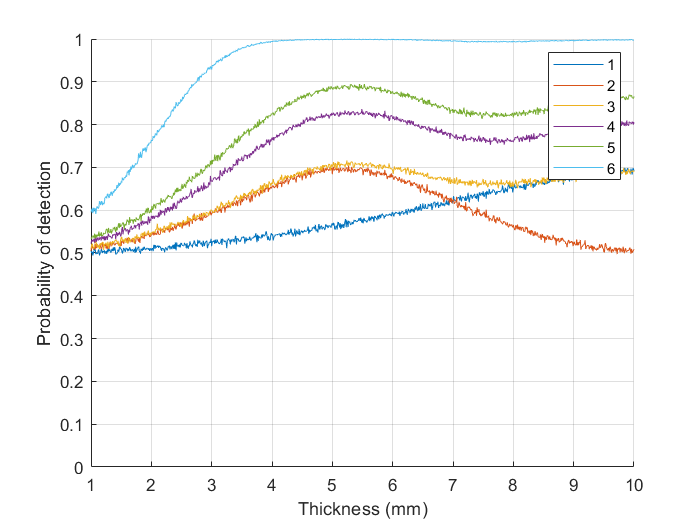

% 
% % %Figure 3
% hold on;
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 3, raw12, raw23_4GHz),  0, theta))));
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 2.9, raw12, raw23_4GHz),  0, theta))));
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 3.3, raw12, raw23_4GHz),  0, theta))));
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 3, raw12, raw23_12GHz),  0, theta))));
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 2.9, raw12, raw23_12GHz),  0, theta))));
% plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 3.3, raw12, raw23_12GHz),  0, theta))));
% grid on;
% hold off;
% clf;
% tic
figure;
hold on;
probability_of_detection(1, [4], 0.5, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
ylim([0 1])
probability_of_detection(1, [8], 0.5, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
probability_of_detection(1, [4 8], 0.5, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
probability_of_detection(3, [4 8], 0.5, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
probability_of_detection(5, [4 8], 0.5, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
probability_of_detection(5, [4 8], 0, 0.01, 0.02, 10000, 3, 1, 20, 35, 0 );
% probability7 
hold off;
% figure;
% 
legend("1", "2", "3", "4", "5", "6")

% grid on; 
% 
% 
% hold off;
% 
% toc

